clear
load data2.mat

T=5; %[s]
fs=1/T; %[Hz]

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);
day=24*60*60*fs

day = 17280

t=T*(2*day:3*day);
X=X';
X=X(:,2*day:3*day);
size(X)

ans =            8       17281


n=length(t);
X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,5;-5,5];
for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

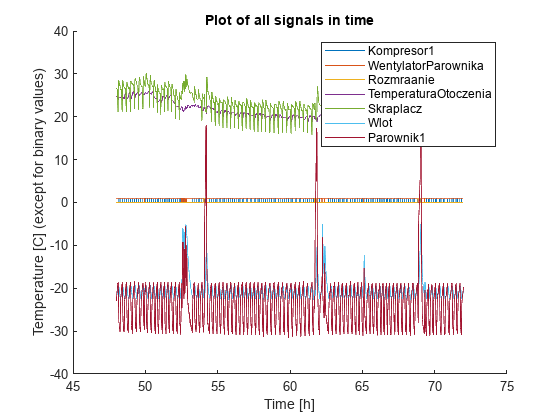

figure
hold on
for i = 2:4
    plot(t/(60*60),(X(i,:)))
end
for i = 1:4
    plot(t/(60*60),(X_filtered(i,:)))
end
xlabel('Time [h]')
ylabel('Temperature [C] (except for binary values)')
title('Plot of all signals in time')
legend('Kompresor1','WentylatorParownika','Rozmraanie',...
    'TemperaturaOtoczenia','Skraplacz','Wlot','Parownik1')
hold off

locs=compressorCycles(X(2,:));

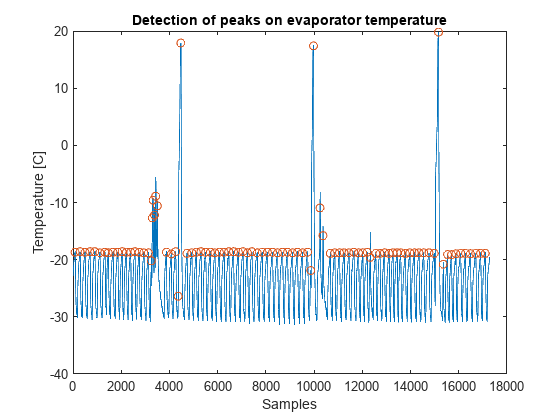

x = FeatureExtract(X_filtered(4,:),locs);
plot((X_filtered(4,:)));hold on
plot(locs,(X_filtered(4,locs)),'o');hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

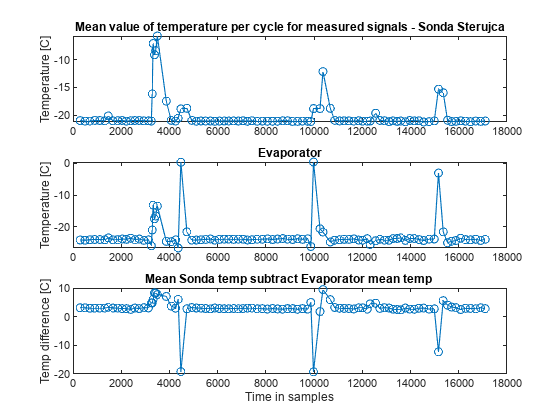

x_wlot = FeatureExtract(X_filtered(3,:),locs);
x_parownik = FeatureExtract(X_filtered(4,:),locs);
locs=locs(2:end);
figure

subplot(311)
plot(locs,x_wlot(3,:),'o-')
title('Mean value of temperature per cycle for measured signals - Sonda Sterujca')
ylabel('Temperature [C]')
% ylim([4,7])
subplot(312)
plot(locs,x_parownik(3,:),'o-')
title('Evaporator')
ylabel('Temperature [C]')
% ylim([4,7])
subplot(313)
plot(locs,x_wlot(3,:)-x_parownik(3,:),'o-')
title('Mean Sonda temp subtract Evaporator mean temp ')
xlabel('Time in samples')
ylabel('Temp difference [C]')

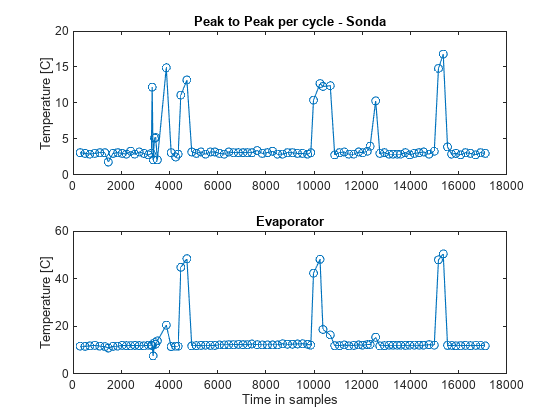

figure

subplot(211)
plot(locs,x_wlot(1,:)-x_wlot(2,:),'o-')
title('Peak to Peak per cycle - Sonda')
ylabel('Temperature [C]')
% ylim([4,7])
subplot(212)
plot(locs,x_parownik(1,:)-x_parownik(2,:),'o-')
title('Evaporator')
ylabel('Temperature [C]')
xlabel('Time in samples')

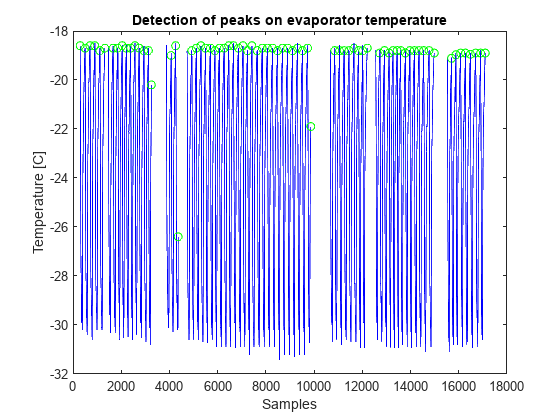

fridge_air_temp_p2p=x_wlot(1,:)-x_wlot(2,:);
figure
TF = isoutlier(fridge_air_temp_p2p);
plot(locs(1),(X_filtered(4,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    if (TF(i)==0)
        plot(locs(i-1):locs(i),(X_filtered(4,locs(i-1):locs(i))),"Color",'blue');
        plot(locs(i),(X_filtered(4,locs(i))),'Marker','o',"Color",'green');
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')